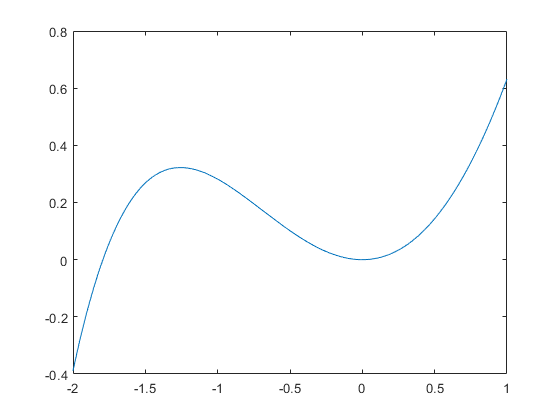

f=@(x)x.^2-x+1-exp(-x);
x=-2:0.001:1;
x0=[0.2 -1.7];
der=@(x,y)(x-y)./0.001;

%question 1
plot(x,f(x))


%question 2

%options=optimoptions('fsolve','Tolfun',10^(-10));
options=optimset('Tolfun',10^(-10),'Display','iter');
fsolve(f,x0)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


ans =     0.0066   -1.7933



options=optimset('Tolfun',10^(-12));
fsolve(f,x0)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


ans =     0.0066   -1.7933



%question 3
er=[1 1];
i=0;

while (er(1)>10^(-10) & er(2)>10^(-10))
    i=i+1;
    o=-f(x0)./der(f(x0+0.001),f(x0));
    x0=x0+o;
    er=abs(o)./abs(x0);
end
x0

x0 =     0.0038   -1.7933


er

er =     0.8742    0.0000


i

i = 6